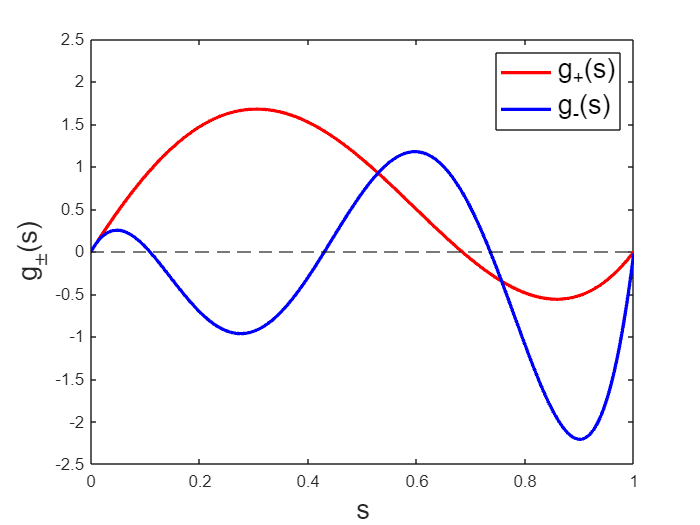

N = 1000;
eta = exp(-pi*1i/8);

xi_values = (2*(1:N) - 1)./(2*N);
Sp = 4.7;

        G_prime = zeros(N, N);
        
        for b = 1:N
            xi = xi_values(b);
            x_minus = xi_values(1:b);
            x_plus = xi_values(b:N);
        
            M = [1 1 1 1 0 0 0 0; 1 1i -1 -1i 0 0 0 0; 0 0 0 0 exp(Sp*eta) exp(Sp*eta*1i) exp(-Sp*eta) exp(-Sp*eta*1i); 0 0 0 0 exp(Sp*eta) 1i*exp(Sp*eta*1i) -exp(-Sp*eta) -1i*exp(-Sp*eta*1i); -exp(Sp*eta*xi) -exp(Sp*eta*1i*xi) -exp(-Sp*eta*xi) -exp(-Sp*eta*1i*xi) exp(Sp*eta*xi) exp(Sp*eta*1i*xi) exp(-Sp*eta*xi) exp(-Sp*eta*1i*xi);  -exp(Sp*eta*xi) -1i*exp(Sp*eta*1i*xi) exp(-Sp*eta*xi) 1i*exp(-Sp*eta*1i*xi) exp(Sp*eta*xi) 1i*exp(Sp*eta*1i*xi) -exp(-Sp*eta*xi) -1i*exp(-Sp*eta*1i*xi);  -exp(Sp*eta*xi) exp(Sp*eta*1i*xi) -exp(-Sp*eta*xi) exp(-Sp*eta*1i*xi) exp(Sp*eta*xi) -exp(Sp*eta*1i*xi) exp(-Sp*eta*xi) -exp(-Sp*eta*1i*xi);  -exp(Sp*eta*xi) 1i*exp(Sp*eta*1i*xi) exp(-Sp*eta*xi) -1i*exp(-Sp*eta*1i*xi) exp(Sp*eta*xi) -1i*exp(Sp*eta*1i*xi) -exp(-Sp*eta*xi) 1i*exp(-Sp*eta*1i*xi)];
            coeff = linsolve(M, [0; 0; 0; 0; 0; 0; 0; 1/((Sp^3)*(eta^3))]);
        
            G_prime((1:b),b) = Sp*eta*(coeff(1)*exp(Sp*eta*x_minus) + 1i*coeff(2)*exp(Sp*eta*x_minus*1i) - coeff(3)*exp(-Sp*eta*x_minus) - 1i*coeff(4)*exp(-Sp*eta*x_minus*1i));
        
            G_prime((b:N),b) = Sp*eta*(coeff(5)*exp(Sp*eta*x_plus) + 1i*coeff(6)*exp(Sp*eta*x_plus*1i) - coeff(7)*exp(-Sp*eta*x_plus) - 1i*coeff(8)*exp(-Sp*eta*x_plus*1i));
        
        end
        G_s = -0.5*(imag(G_prime) + imag(G_prime.'));
        
        G_swim = G_s;
        
        [A, B] = eig(G_swim);

        g_plus = A(:, end)*sqrt(N);
        g_minus = A(:, end-1)*sqrt(N);


plot(xi_values, g_plus, 'r', 'LineWidth', 2)
hold on
plot(xi_values, g_minus, 'b', 'LineWidth', 2)
xlim([0, 1])
ylim([-2.5, 2.5])
yline(0, '--k')

xlabel('s', 'FontSize', 16)
ylabel('g_\pm(s)', 'FontSize', 16)
legend('g_+(s)', 'g_-(s)', 'FontSize', 16)